For the document network data, the input is two matrices including the m x n document content matrix W and the m x m citation link matrix C

clear classes

clear all
close all
clc

rng(213);        % code initialized
load('../Data/cora.mat');    % the sythetic temporary data file

%    W -- m x n     C -- m x m
lx = categorical(paper_classname);
[M, ~] = size(W);

Show the matrix structure

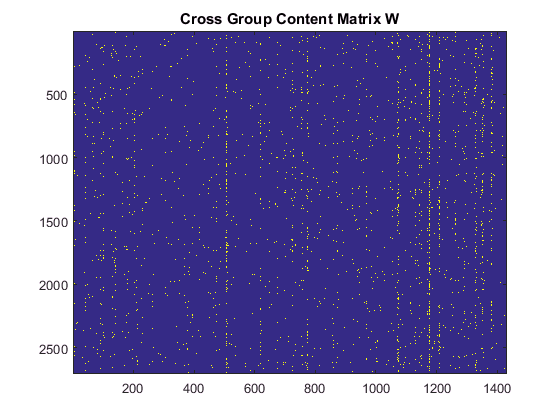

figure
imagesc(W);
title('Cross Group Content Matrix W');

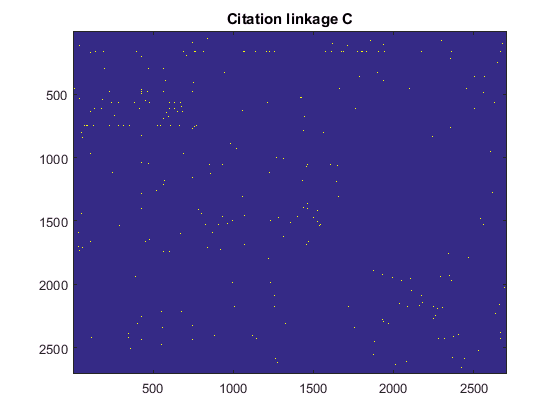


figure
C = C | C.';
imagesc(C);
title('Citation linkage C');

Using linear Transformation and Laplcian for dimensionality reduction

% %Normalized input data
% W = W - min(W(:));   % W = [k*C, W]; result in a lot of small eigenvalues
% W = W/max(W(:));
% W = bsxfun(@minus, W, mean(W,1));
% 
% d = sum(C,2);
% rd = 1./sqrt(d);
% Lc =  eye(M) - bsxfun(@times,bsxfun(@times,C,rd), rd');
% Lc = W'*Lc*W;
% 
% C_ = ~C;
% d_ = sum(C_,2);
% rd_ = 1./sqrt(d_);
% Lc_ =  eye(M) - bsxfun(@times,bsxfun(@times,C_,rd_), rd_');
% Lc_ = W'*Lc_*W;
% [P, Lambda] = eig(Lc, Lc_);
% [~, I] = sort(diag(Lambda), 'ascend');
% X = W*P;
% figure
% Plotcluster(X(:, [I(2),I(3)])', lx);
% title('Linear Laplacian embedding using C and W');

Revision No. 1

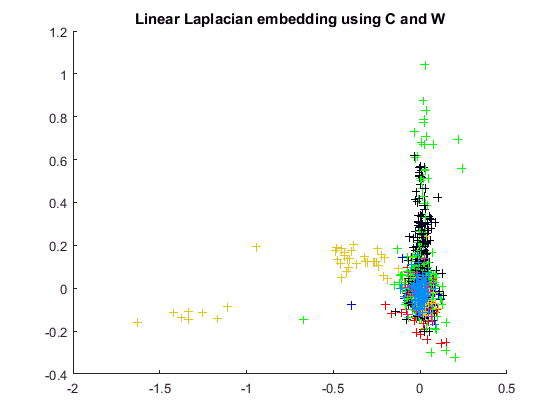

%Normalized input data
W = W - min(W(:));   % W = [k*C, W]; result in a lot of small eigenvalues
W = W/max(W(:));
W = bsxfun(@minus, W, mean(W,1));

d = sum(C,2);
Lc =  diag(d) - C;
Lc = W'*Lc*W;

C_ = ~C;
d_ = sum(C_,2);
Lc_ =  diag(d_) - C_;
Lc_ = W'*Lc_*W;
[P, Lambda] = eig(Lc, Lc_);
[~, I] = sort(diag(Lambda), 'ascend');
X = W*P;
figure
Plotcluster(X(:, [I(2),I(3)])', lx);
title('Linear Laplacian embedding using C and W');

% d = sum(T,2);        % T = [C, lambda*D];
% rd = 1./sqrt(d);
% Lc =  eye(size(T,1)) - bsxfun(@times,bsxfun(@times,T,rd), rd');
% [P, Lambda] = eig(Lc);
% [~, I] = sort(diag(Lambda), 'ascend');
% figure
% Plotcluster(P(:, [I(2),I(1)])', lx);
% title('Linear Laplacian embedding using C and W');